## Interpretation

Given our results, we can first conclude that it is indeed possible to launch a human to the moon, as long as some assumptions are made. Our model sweeps through multiple values of angles and velocities in order to determine the most optimal angle and velocity for launch. We've concluded that the slowest speed required in order to hit the moon is a launch speed of __ at a launch angle of __ degrees. 

We think that the sets of answers that we've reached aren't the best, but given the limitations of ode and assumptions we've made, we think that the answers we've reached are valid. First of all, our margin of error creates a 'planet' that's larger than Jupiter. Jupiter has a radius of 69911 km, and the “Moon” has a radius of 76380 km, making our "Moon" the largest planet in our solar system. The reason we had to expand our margin of error to this degree is because of the time steps that ode takes. If you launch the human at a speed too quick, ode will think that there's a straight line and that the slope of the graph doesn't change often, therefore ode expands the increments of the time steps. Our event function requires the smaller steps in order to determine when the projectile hits the Moon, but currently, since the time steps are located before and after the moon, the event function doesn't stop the simulation and the projectile continues to fly past (or even through) the Moon.

Parameter sweeping finds values are very computationally taxing, therefore we weren’t able to get the most optimal values for velocities and angles since the velocities jumped in increments of 10 m/s, and the angles in 1-degree increments. Originally our model looked like the one below, but it took too long to run:

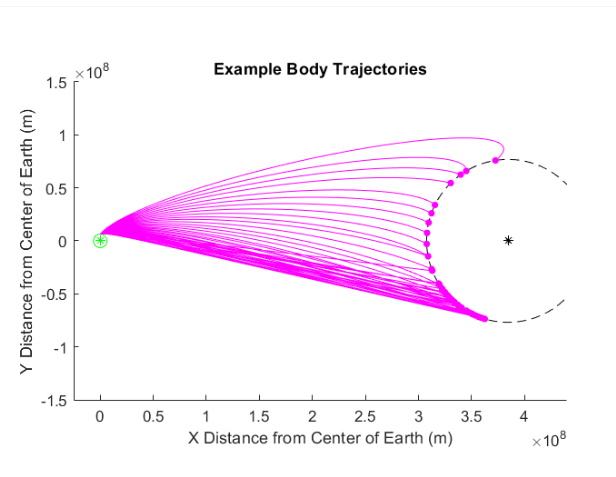

Our current model has velocities jumping in increments of 100 m/s, and the angles in 1-degree increments, which is much less optimized than our original.

Another limitation is the lack of an atmosphere in our model, which assumes no air resistance. This isn’t realistic because air resistance is a large factor when it comes to escape velocities and leaving the Earth’s atmosphere. Depending on the shape of the object launched and how much mass it has, this air drag can have a stronger or weaker effect.

If given more time for our model, we would attempt to circumvent the limitations of ODE by using a different time-step method, like Euler’s method, although that would also be computationally expensive. This would allow us to significantly decrease the margin of error, and make our model more accurate. We would also want to make our parameter sweep run at finer increments, in order to truly optimize the model and reach more accurate results than the ones we had to resort to. We would also like to include air resistance in our model, also to more accurately represent a launch from the Earth to the Moon.

--------------------------------------------

Before attempting to optimize our system, we need to create a model that accurately calculates the position of a body shot off of the Earth. We have created `body_2D_ode45() `to simulate our body in space.

% Example body trajectory
launchAngle = 25;
launchVelocity = 12550;

[T, M] = body_2D_ode45(launchAngle, launchVelocity);

clf;
hold on
plot(M(:,1), M(:,2),'m');

% Plot Earth
points = linspace(0, 2*pi, 500); r = 6.371e6;
x = r*cos(points); y = r*sin(points);
plot(x,y,'g'); plot(0,0,'*g')

% Plot Moon
r = 1.738e6;
x = r*cos(points) + 3.844e8; y = r*sin(points);
plot(x,y,'k'); plot(3.844e8,0, '*k')

% Plot lunar satelite orbit
r = 1.738e6 + 50000*1000;
x = r*cos(points) + 3.844e8; y = r*sin(points);
plot(x,y,'--k')
plot(M(end, 1), M(end, 2), "m.", "MarkerSize", 15)

xlabel('X Distance from Center of Earth (m)'); ylabel('Y Distance from Center of Earth (m)');
title('Example Body Trajectory')
axis equal; xlim([-0.25*10^8 4.4*10^8]); ylim([-1.5*10^8 1.5*10^8]);

Now that we have a working model, we can input some different values to simulate some different results. 

% Body trajectory examples
clf;
hold on

% Plot Earth
points = linspace(0, 2*pi, 500); r = 6.371e6;
x = r*cos(points); y = r*sin(points);
plot(x,y,'g'); plot(0,0,'*g')

% Plot Moon
r = 1.738e6;
x = r*cos(points) + 3.844e8; y = r*sin(points);
plot(x,y,'k'); plot(3.844e8,0, '*k')

% Plot lunar satelite orbit
r = 1.738e6 + 50000*1000;
x = r*cos(points) + 3.844e8; y = r*sin(points);
plot(x,y,'--k')

launchAngle = 25;
launchVelocity = 12470;
[T, M] = body_2D_ode45(launchAngle, launchVelocity);
plot(M(:,1), M(:,2),'m');
plot(M(end, 1), M(end, 2), "m.", "MarkerSize", 15)

launchAngle = 30;
launchVelocity = 11900;
[T, M] = body_2D_ode45(launchAngle, launchVelocity);
plot(M(:,1), M(:,2),'m');
plot(M(end, 1), M(end, 2), "m.", "MarkerSize", 15)

launchAngle = 35;
launchVelocity = 11500;
[T, M] = body_2D_ode45(launchAngle, launchVelocity);
plot(M(:,1), M(:,2),'m');
plot(M(end, 1), M(end, 2), "m.", "MarkerSize", 15)

xlabel('X Distance from Center of Earth (m)'); ylabel('Y Distance from Center of Earth (m)');
title('Example Body Trajectories')
axis equal; xlim([-0.25*10^8 4.4*10^8]); ylim([-1.5*10^8 1.5*10^8]);

As you can see, our model stops the simulation when the body gets within 50,000km of the Moon. We can now used this to optimize our model.

% Body trajectory examples
clf;
hold on

% Plot Earth
points = linspace(0, 2*pi, 500); r = 6.371e6;
x = r*cos(points); y = r*sin(points);
plot(x,y,'g'); plot(0,0,'*g')

% Plot Moon
r = 1.738e6; % Radius of the Moon
x = r*cos(points) + 3.844e8; y = r*sin(points);
plot(x,y,'k'); plot(3.844e8,0, '*k')

% Plot lunar satelite orbit
r = 1.738e6 + 75000*1000; % Radius of the Margin of Error
x = r*cos(points) + 3.844e8; y = r*sin(points);
plot(x,y,'--k')

% Parameter Sweep

optimizedVelocity = [];

for launchAngle = 0:1:80
    disp(launchAngle) % Do we still need this display right here, 
                      % or was it just to confirm the code works?
    flag = 0;
    for launchVelocity = 10000:10:16000
        [T, M] = body_2D_ode45(launchAngle, launchVelocity);
        if T(end) ~= 60*60*24*7
            optimizedVelocity = [optimizedVelocity; launchVelocity];
            plot(M(:,1), M(:,2),'m');
            plot(M(end, 1), M(end, 2), "m.", "MarkerSize", 15)
            flag = 1;
        end
        if flag == 1
            break;
        end
    end 
end

xlabel('X Distance from Center of Earth (m)'); ylabel('Y Distance from Center of Earth (m)');
title('Example Body Trajectories')
axis equal; xlim([-0.25*10^8 4.4*10^8]); ylim([-1.5*10^8 1.5*10^8]);

% Verification using Energy

launchAngle = 25;
launchVelocity = 12550;

[T, M] = body_2D_ode45(launchAngle, launchVelocity);

G = 6.67e-11; % Gravitational Constant ((N*m^2)/kg^2)
earthMass = 5.97e24; % (kg)
moonMass = 7.348e22; % Mass of the Moon (kg)
bodyMass = 60; % Mass of the body being fired out of our cannon (kg)
rEarth = 6.371e6; % Radius of the Earth
rMoon = 1.738e6; % 

position = sqrt((M(:,1).^2) + (M(:,2).^2));

speed = sqrt((M(:,3).^2) + (M(:,4).^2));

PE = ((G*bodyMass*earthMass)./(position.^2)) .* (position - rEarth);
KE = 0.5*bodyMass*(speed.^2);

Total_Energy = PE + KE;
plot(T/8.64e3, Total_Energy);
plot(T/8.64e3, PE);
plot(T/8.64e3, KE);

